# Setting up

clc
clear;

addpath('.\sensordata\')
addpath('.\Helper functions\')

run startup.m

Loading: D:\Chalmers\SSY345_Sensor Fusion\Project\Sensorfusion smartphone\sensordata.jar


## Establishing connection

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:39729


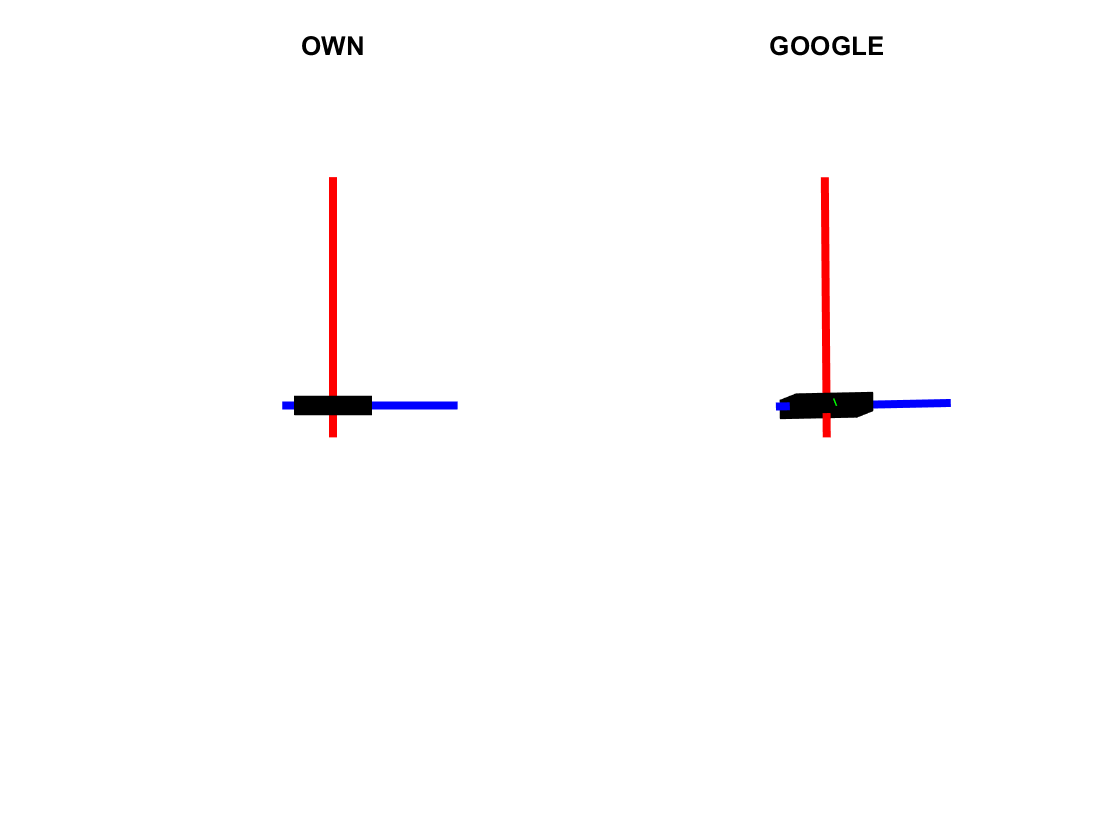

[xhat, meas] = filterTemplate();

## Plotting

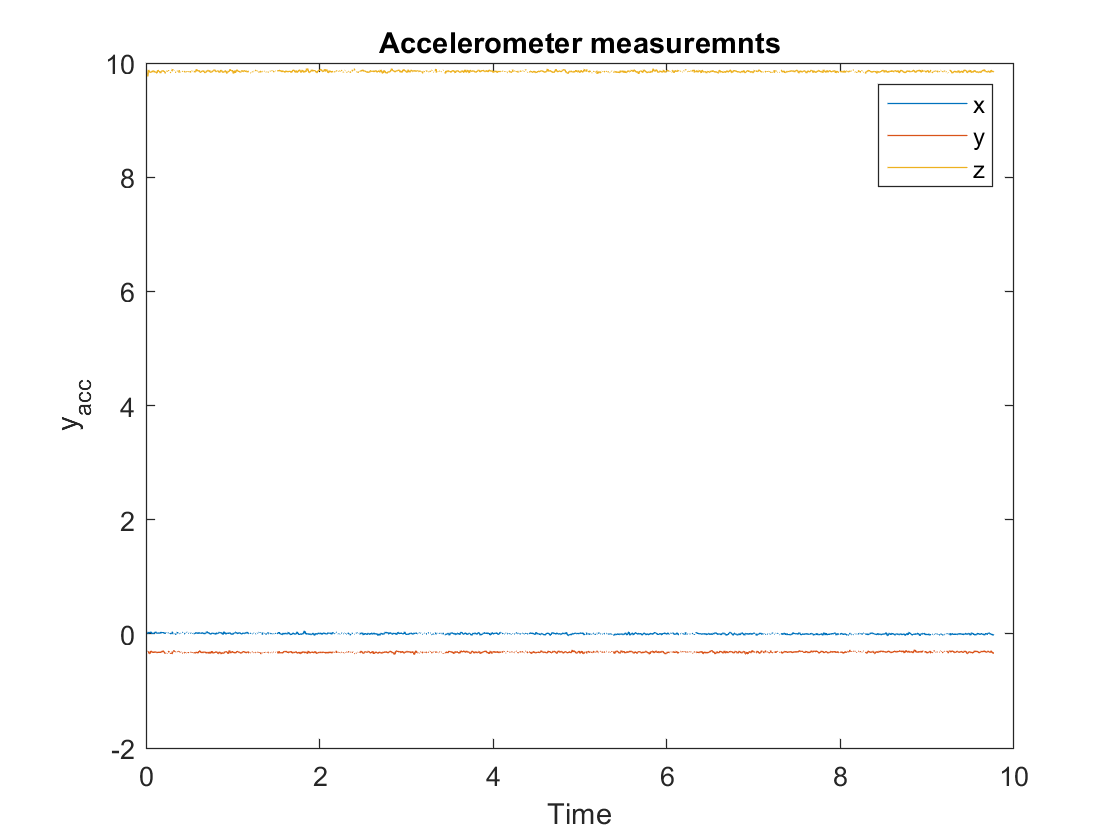

clf;
figure()
plot(meas.t, meas.acc)
title('Accelerometer measuremnts')
legend('x', 'y', 'z')
xlabel('Time'), ylabel('y_{acc}')

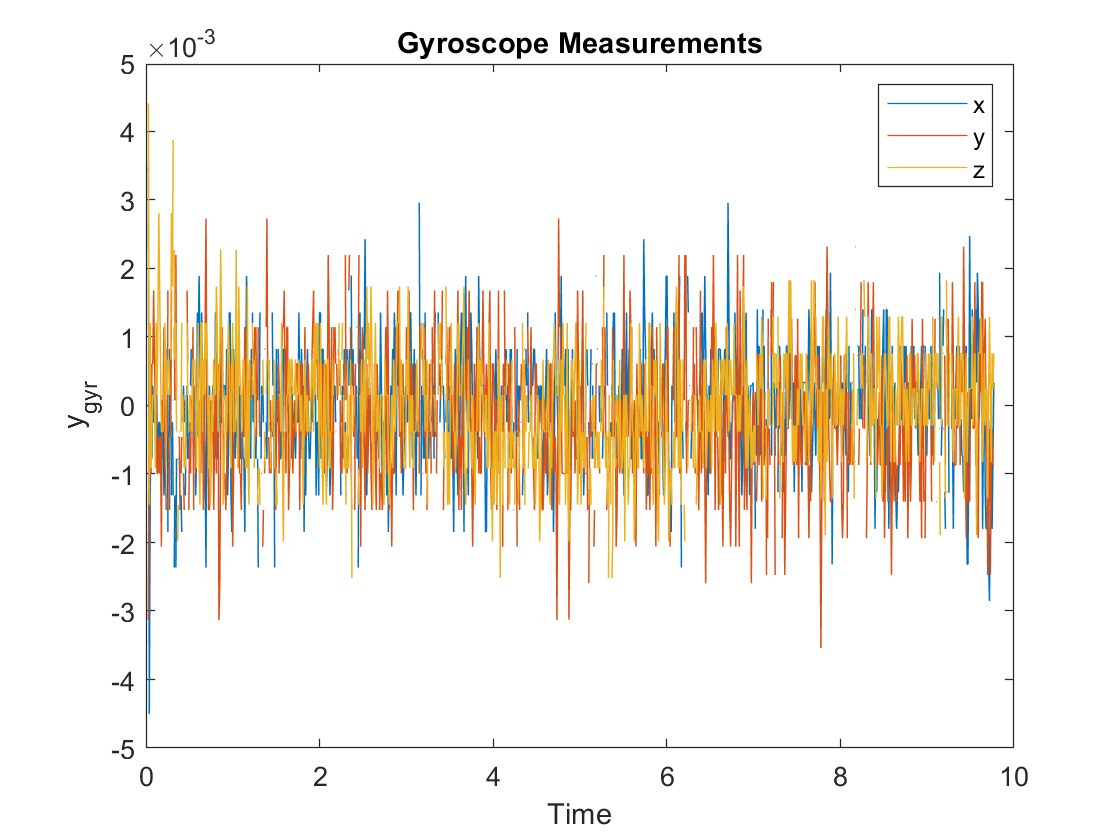

% print('./Images/Acc_meas_flat','-dpng')

figure()
plot(meas.t, meas.gyr)
title('Gyroscope Measurements')
legend('x', 'y', 'z')
xlabel('Time'), ylabel('y_{gyr}')

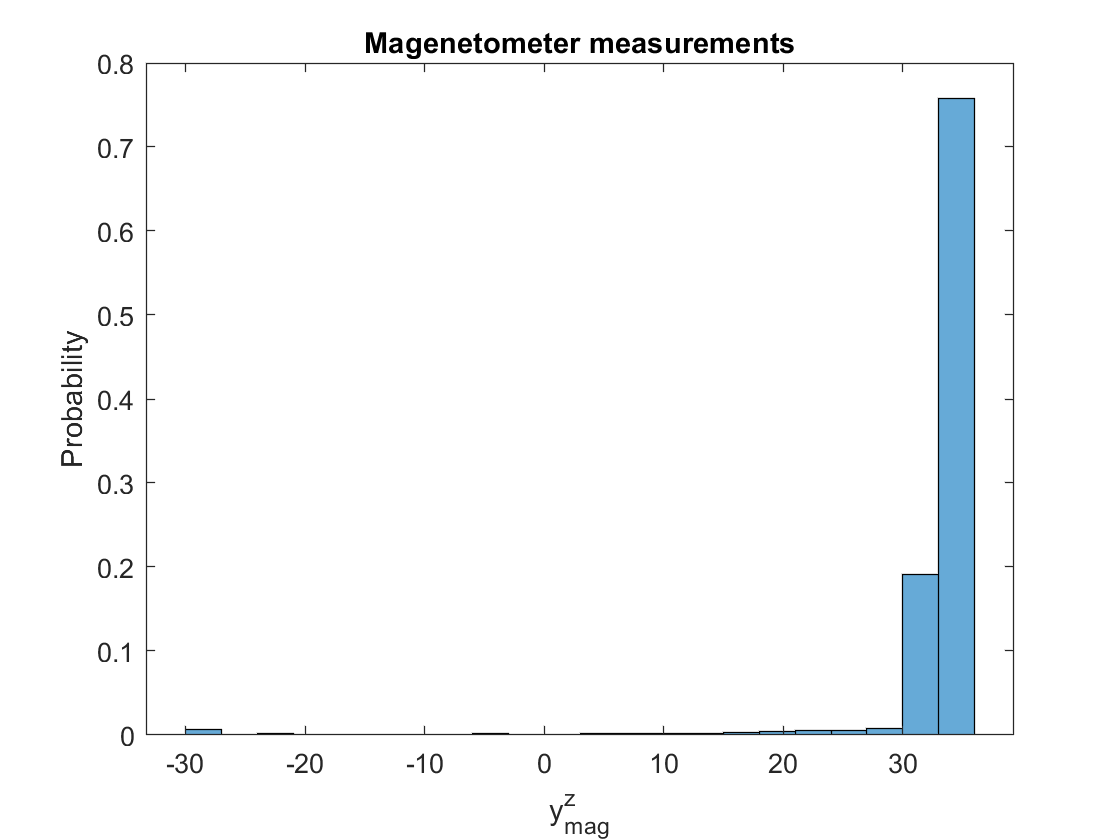

% print('./Images/Gyro_meas_flat','-dpng')

figure()
plot(meas.t, meas.mag)
title('Magnetometer Measurements')
legend('x', 'y', 'z')
xlabel('Time'), ylabel('y_{mag}')

% print('./Images/Mag_meas_flat','-dpng')

## Computing mean and covariance

% Accelerometer measurements
mean_acc = mean(meas.acc(:, ~any(isnan(meas.acc), 1)), 2)

mean_acc =     0.1446
   -0.2757
    9.8556


cov_acc = cov(meas.acc(:, ~any(isnan(meas.acc), 1)).')

cov_acc = 	1.0e+-3 *

    0.1402   -0.0119   -0.0023
   -0.0119    0.1406    0.0079
   -0.0023    0.0079    0.2204


histogram(meas.acc(3, ~any(isnan(meas.acc), 1)), 'Normalization','probability')
% histogram(meas.acc(2, ~any(isnan(meas.acc), 1)))
% histogram(meas.acc(1, ~any(isnan(meas.acc), 1)))
title('Accelerometer measurements')
xlabel('y_{acc}^z'), ylabel('Probability')
% print('./Images/hist_acc_z','-dpng')

% Gyroscope measurements
mean_gyr = mean(meas.gyr(:, ~any(isnan(meas.gyr), 1)), 2)

mean_gyr = 	1.0e+-3 *

    0.0788
   -0.1143
   -0.2260


cov_gyr = cov(meas.gyr(:, ~any(isnan(meas.gyr), 1)).')

cov_gyr = 	1.0e+-6 *

    0.7015    0.0345    0.0110
    0.0345    0.9876   -0.0331
    0.0110   -0.0331    0.6969


histogram(meas.gyr(2, ~any(isnan(meas.gyr), 1)), 'Normalization','probability')
title('Gyrometer measurements')
xlabel('y_{gyr}^y'), ylabel('Probability')
% print('./Images/hist_gyr_y','-dpng')

% Magnetometer measurements
mean_mag = mean(meas.mag(:, ~any(isnan(meas.mag), 1)), 2)

mean_mag =    -4.6283
   17.6877
  -42.0686


cov_mag = cov(meas.mag(:, ~any(isnan(meas.mag), 1)).')

cov_mag =     1.6876   -4.3161    6.3567
   -4.3161   11.6916  -17.3521
    6.3567  -17.3521   26.0043


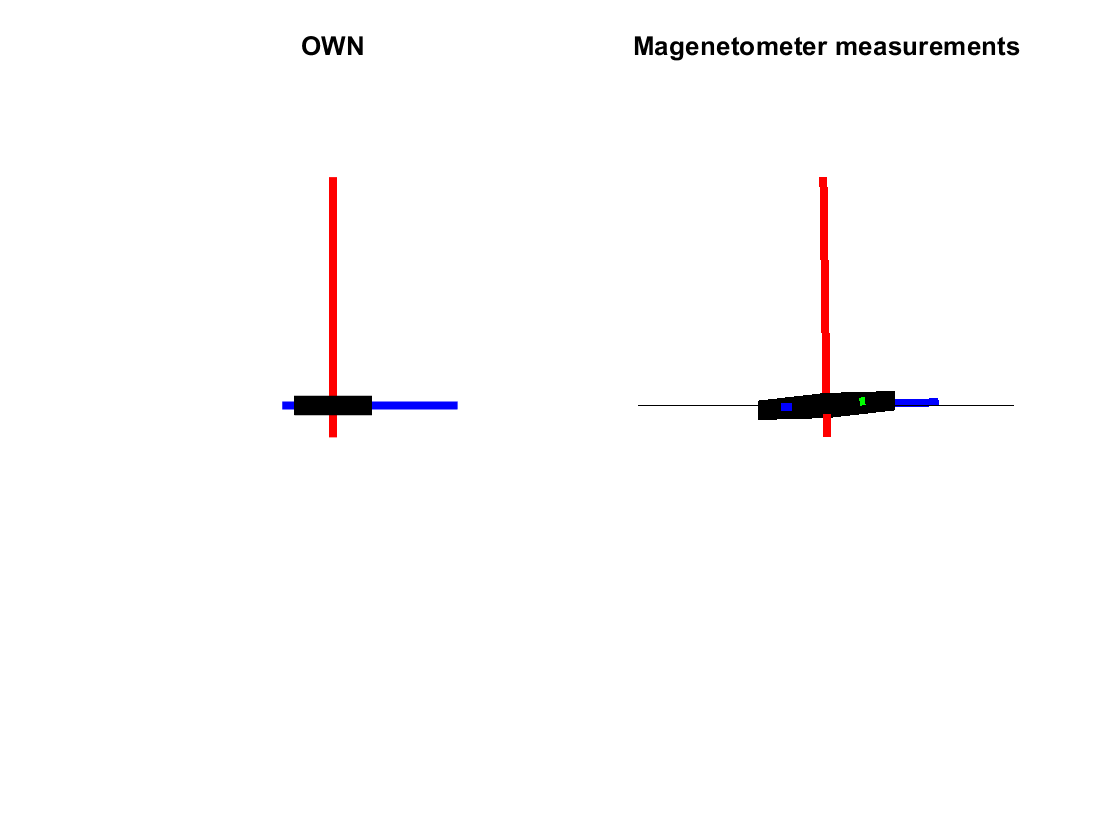

histogram(meas.mag(3, ~any(isnan(meas.mag), 1)), 'Normalization','probability')
title('Magenetometer measurements')
xlabel('y_{mag}^z'), ylabel('Probability')

% print('./Images/hist_mag_z','-dpng')
save flat_data.mat

## Task 4

% Implemented time update function
% Test
x = ones(4,1);
P = rand(4);

omega = rand(3,1);
T = 0.1;
Rw = rand(3);

[x, P] = tu_qw(x, P, omega, T, Rw);
% [x, P] = tu_qw(x, P, gyr, t-xhat.t, P);

## Task 5

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:39475


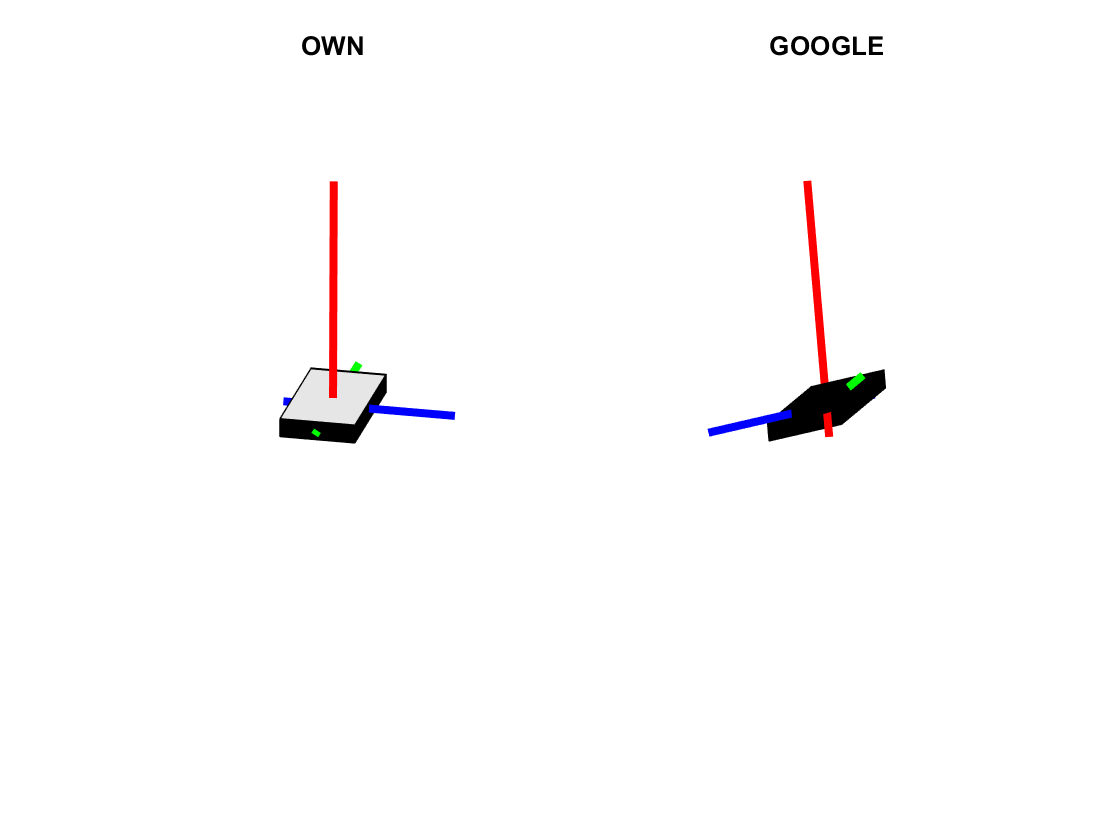

[xhat2, meas2] = Myfilter();

## Plotting the results

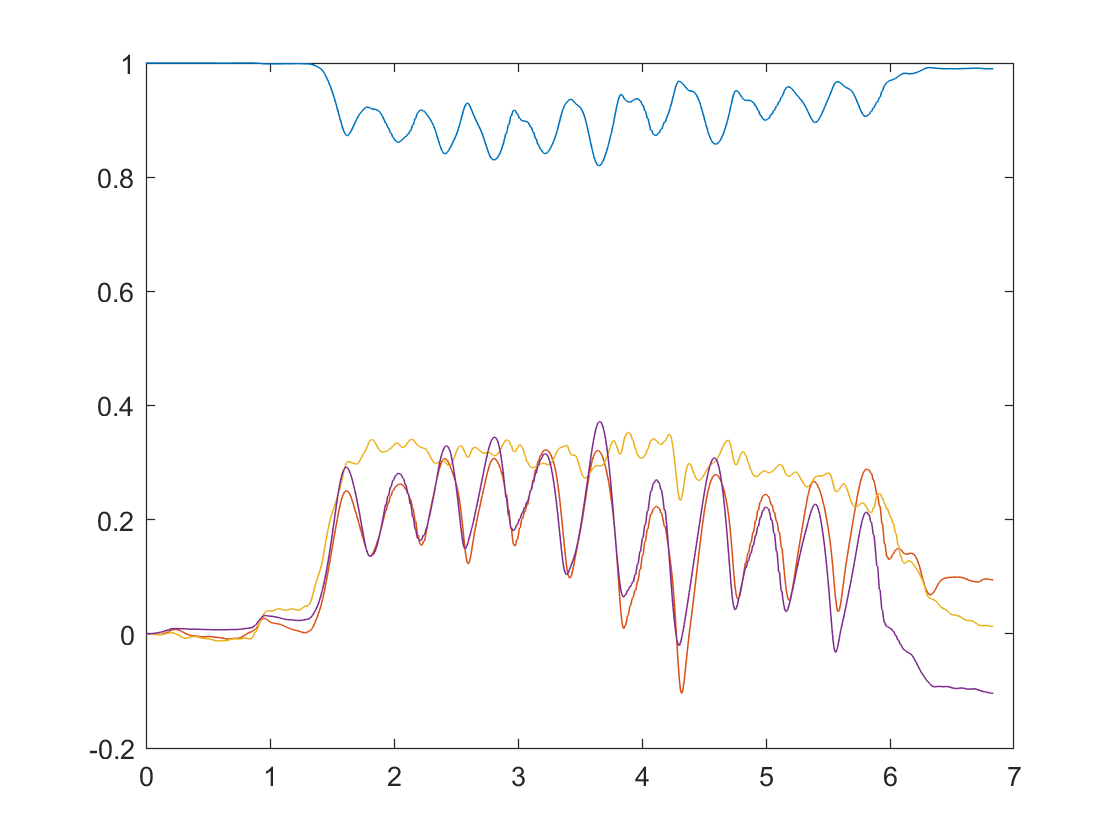

figure()
T_5 = xhat2.t(2:end);
plot(T_5, xhat2.x(1,:))
hold on
plot(T_5, xhat2.x(2,:))
plot(T_5, xhat2.x(3,:))
plot(T_5, xhat2.x(4,:))
hold off

% print('./Images/task5_timeUpdate','-dpng')

## Task 6

% Implemented the acceleromater measurement update
% Test
x = rand(4,1);
P = rand(4);

yacc = rand(3,1);
Ra = cov_acc;
g0 = [0;0;9.81];

[x, P] = mu_g(x, P, yacc, Ra, g0)

x =     0.8185
    1.5352
    2.1545
   -0.9316


P =     0.0157   -0.1508    0.2507   -0.2471
    0.0030   -0.0289    0.0481   -0.0474
   -0.0215    0.2068   -0.3437    0.3387
   -0.0392    0.3769   -0.6266    0.6173


## Task 7

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:39515


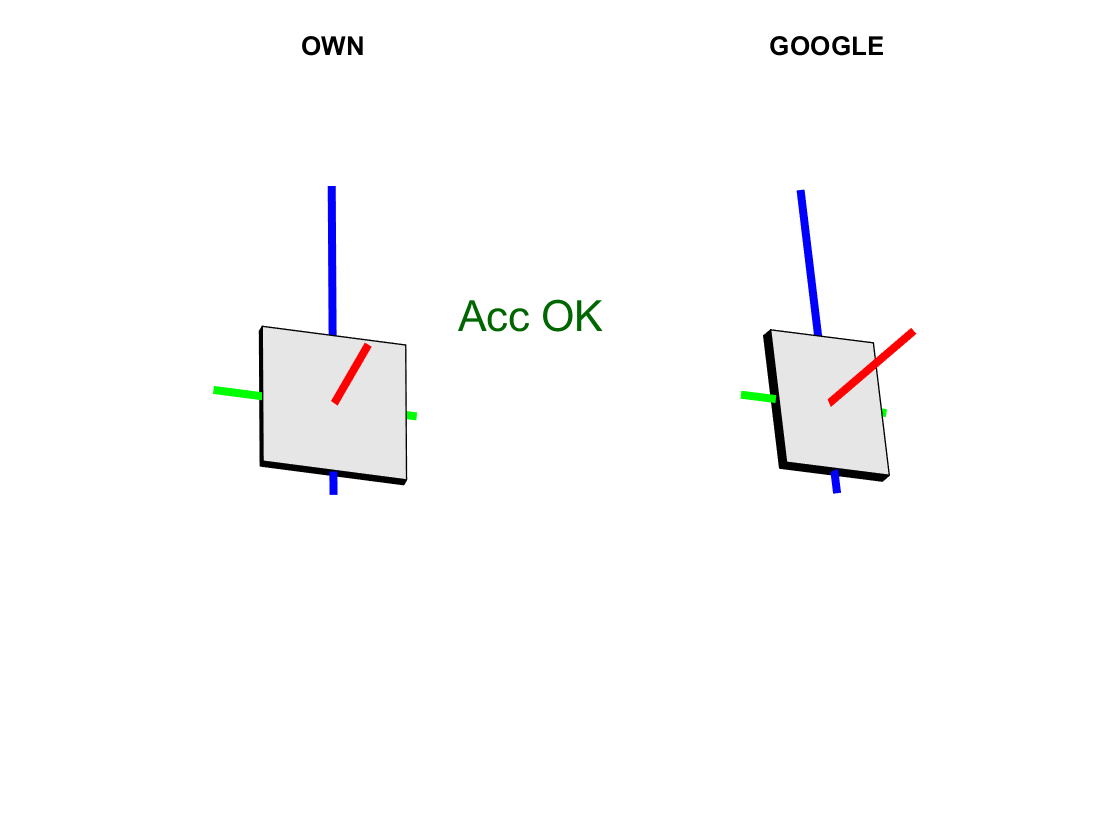

[xhat7, meas7] = Myfilter();

## Plotting after the accelerometer measurement update

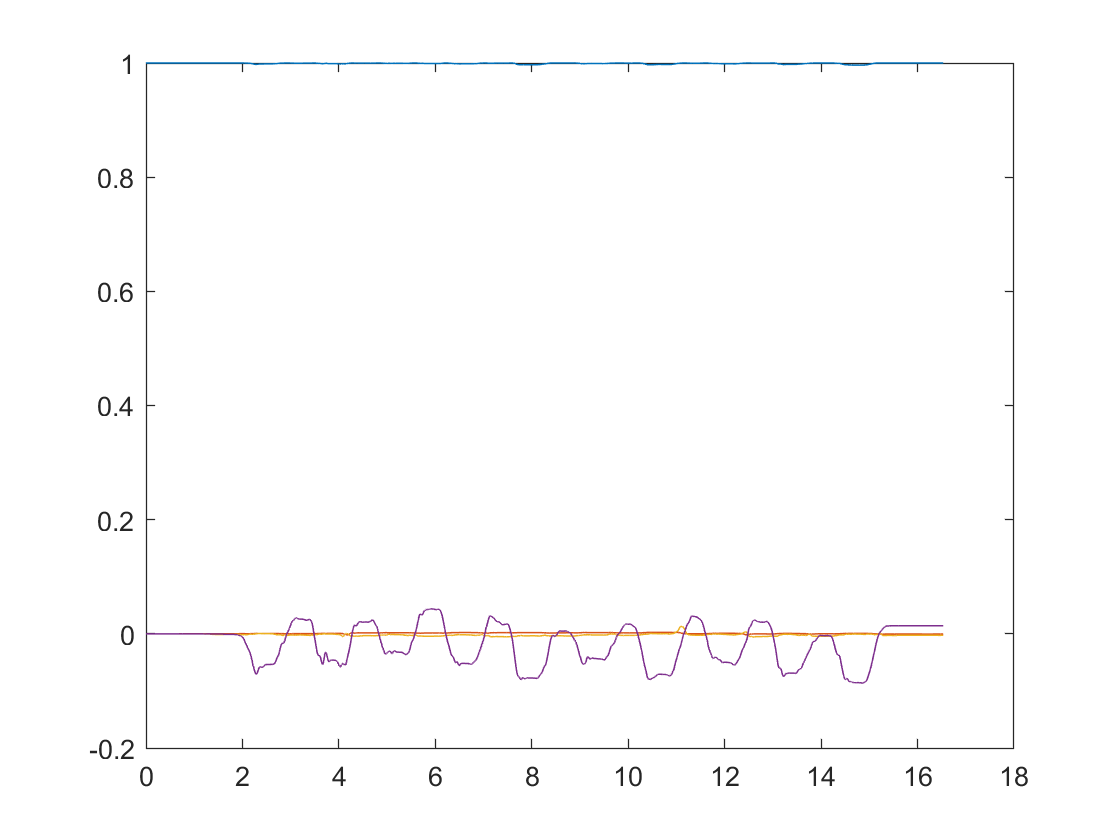

figure()
T_7 = xhat7.t(2:end);
plot(T_7, xhat7.x(1,:))
hold on
plot(T_7, xhat7.x(2,:))
plot(T_7, xhat7.x(3,:))
plot(T_7, xhat7.x(4,:))
hold off
% print('./Images/task7_meas_acc_Update','-dpng')

## Task 8

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:37108


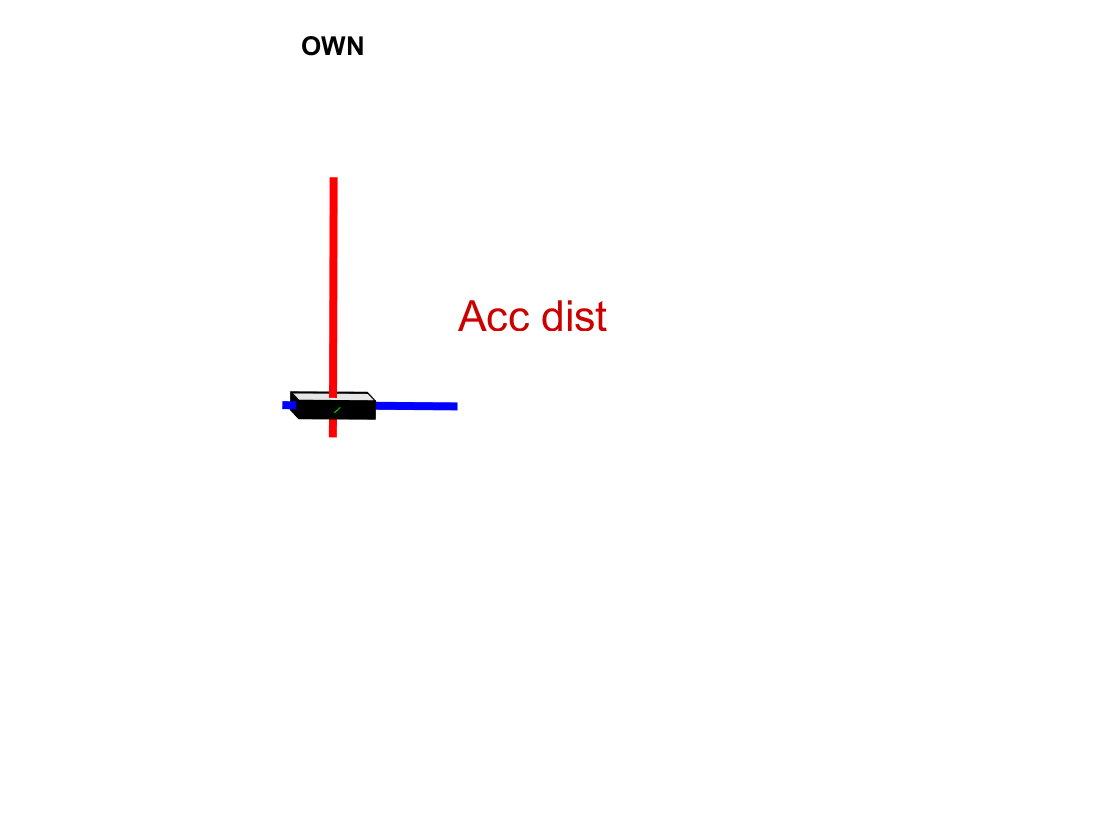

% Implemented the outlier rejection algorithm
[xhat8, meas8] = Myfilter();

## Plotting after the outlier rejection

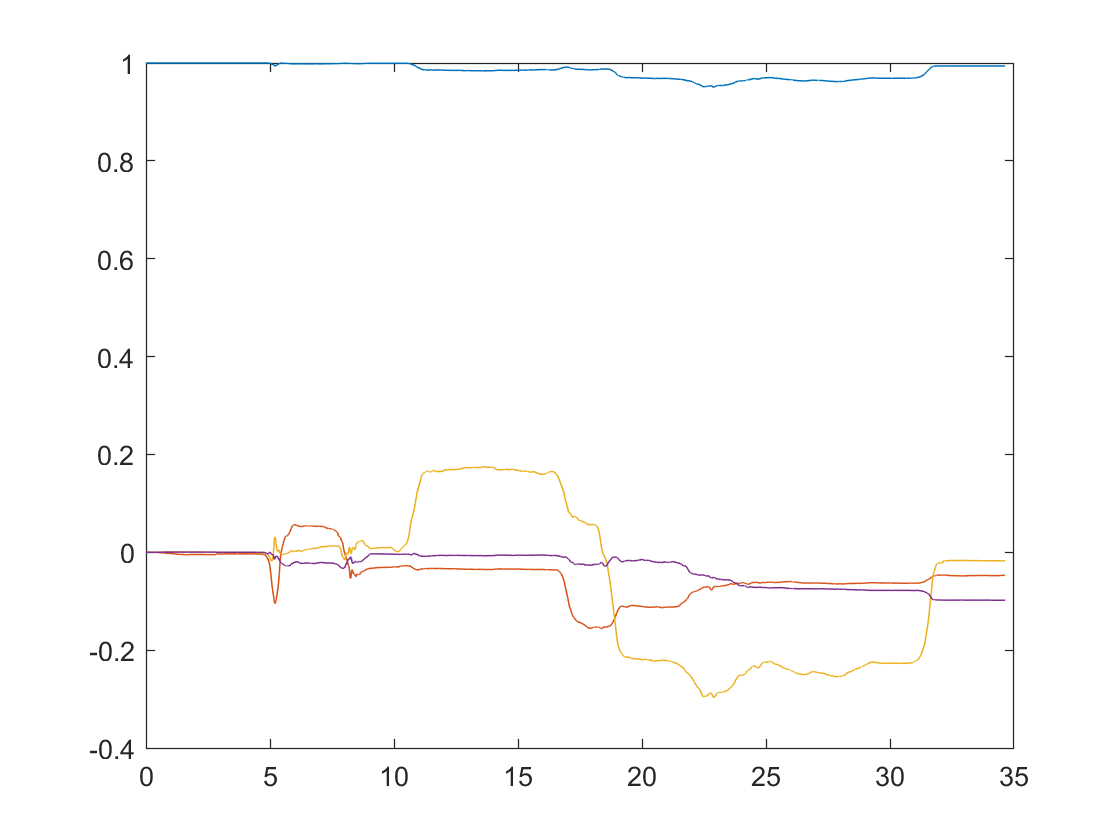

figure()
T_8 = xhat8.t(2:end);
plot(T_8, xhat8.x(1,:))
hold on
plot(T_8, xhat8.x(2,:))
plot(T_8, xhat8.x(3,:))
plot(T_8, xhat8.x(4,:))
hold off

% print('./Images/task8_acc_outlier_rej','-dpng')

## Task 9

% Implemented measurement update using magnetometer measurements
% Test
x = rand(4,1);
P = rand(4);
mag = rand(3,1);
m0 = mean_mag;
Rm = cov_mag;

% [x, P] = mu_m(x, P, mag, m0,Rm)

x =     0.5255
    0.0197
    0.2126
    0.7017


P =     0.0652   -0.0310    0.0078   -0.0020
    0.1112   -0.0530    0.0132   -0.0034
    1.5297   -0.7283    0.1813   -0.0475
    0.5958   -0.2837    0.0706   -0.0185


## Task 10

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:39573


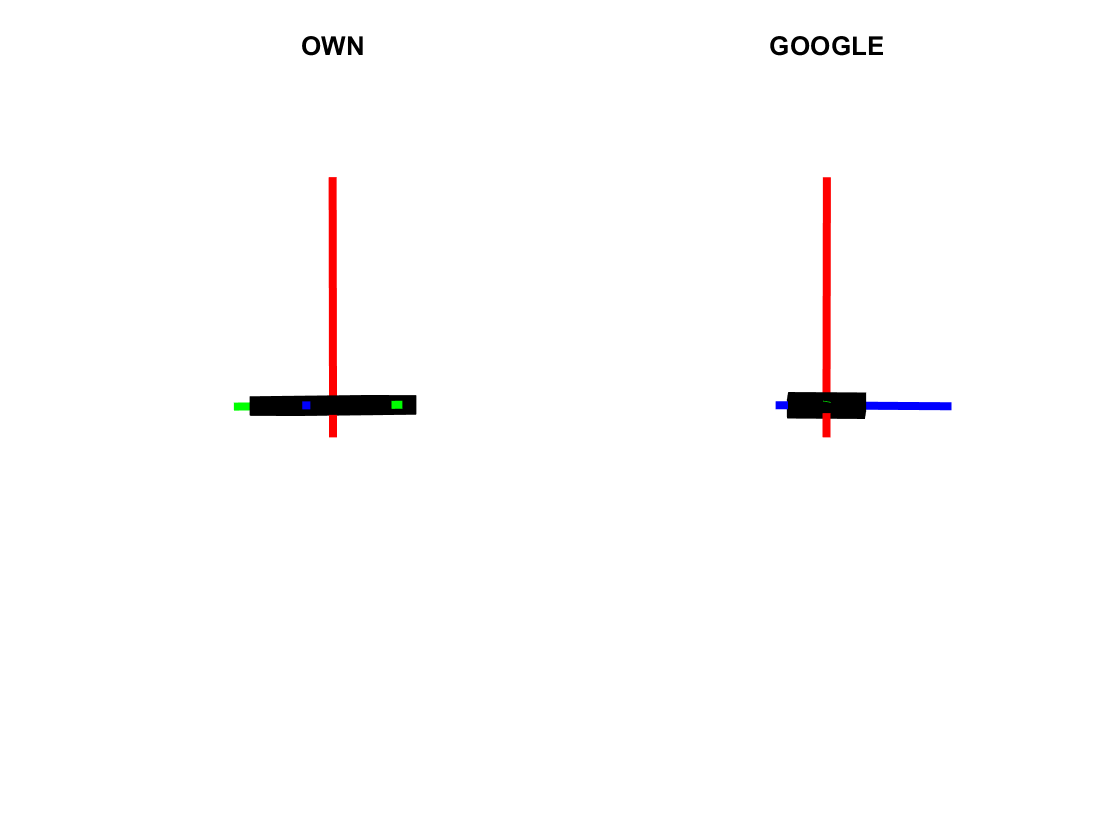

[xhat10, meas10] = Myfilter();

## Plotting q with magnetometer measurement update

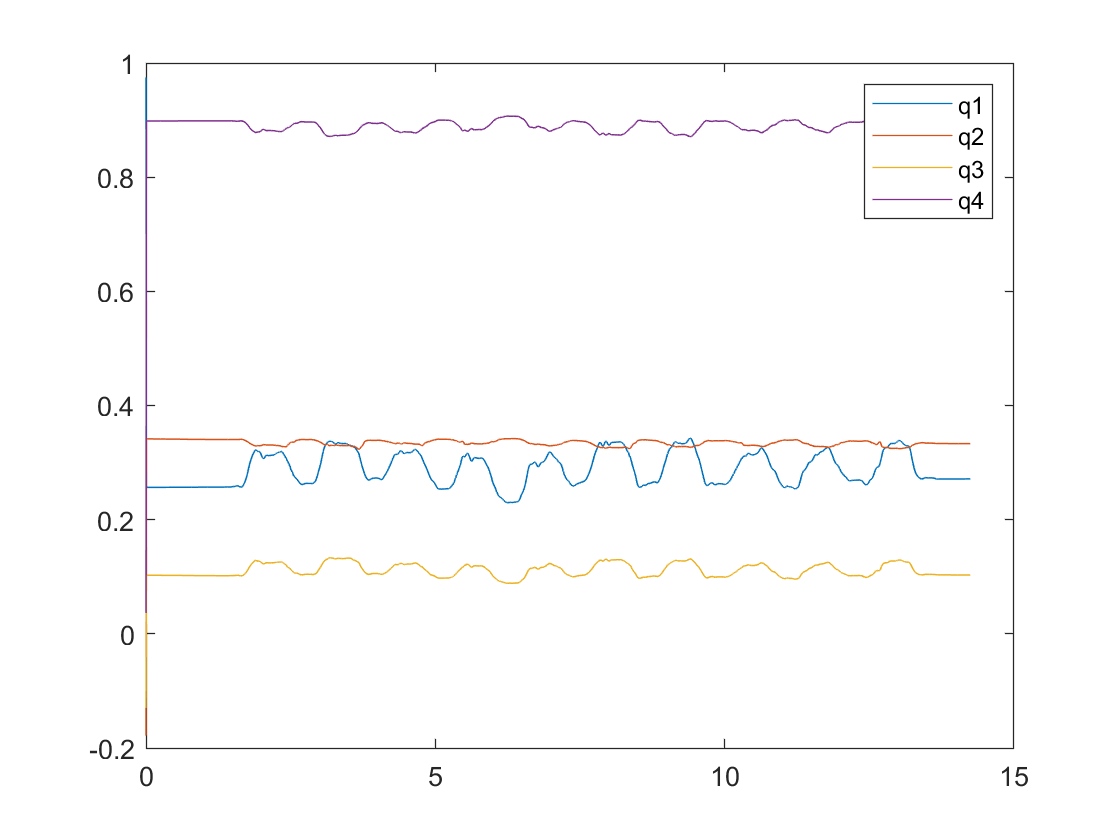

figure()
T_10 = xhat10.t(2:end);
plot(T_10, xhat10.x(1,:))
hold on
plot(T_10, xhat10.x(2,:))
plot(T_10, xhat10.x(3,:))
plot(T_10, xhat10.x(4,:))
hold off
legend('q1', 'q2', 'q3', 'q4')
% print('./Images/task10_meas_mag_Update','-dpng')

## Task 11

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:39791


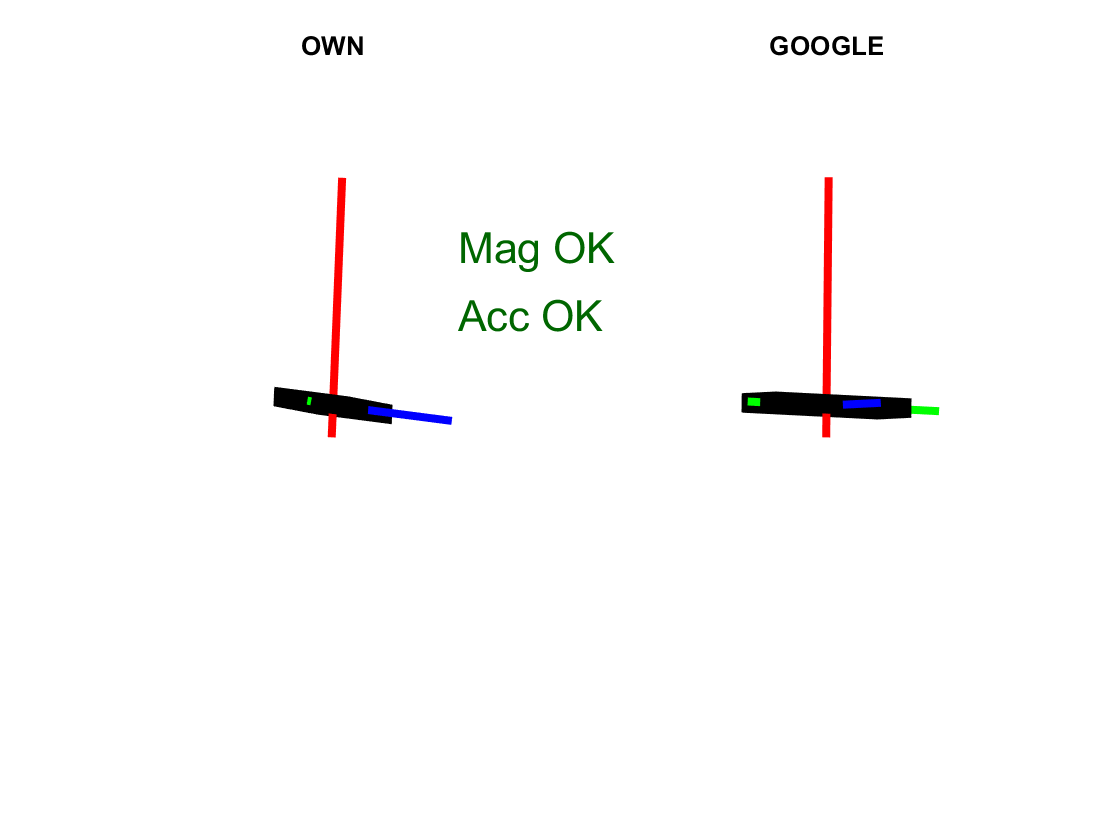

% Implemented the outlier rejection for magnetometer reading
[xhat11, meas11] = Myfilter();

## Plotting the results after outlier rejection

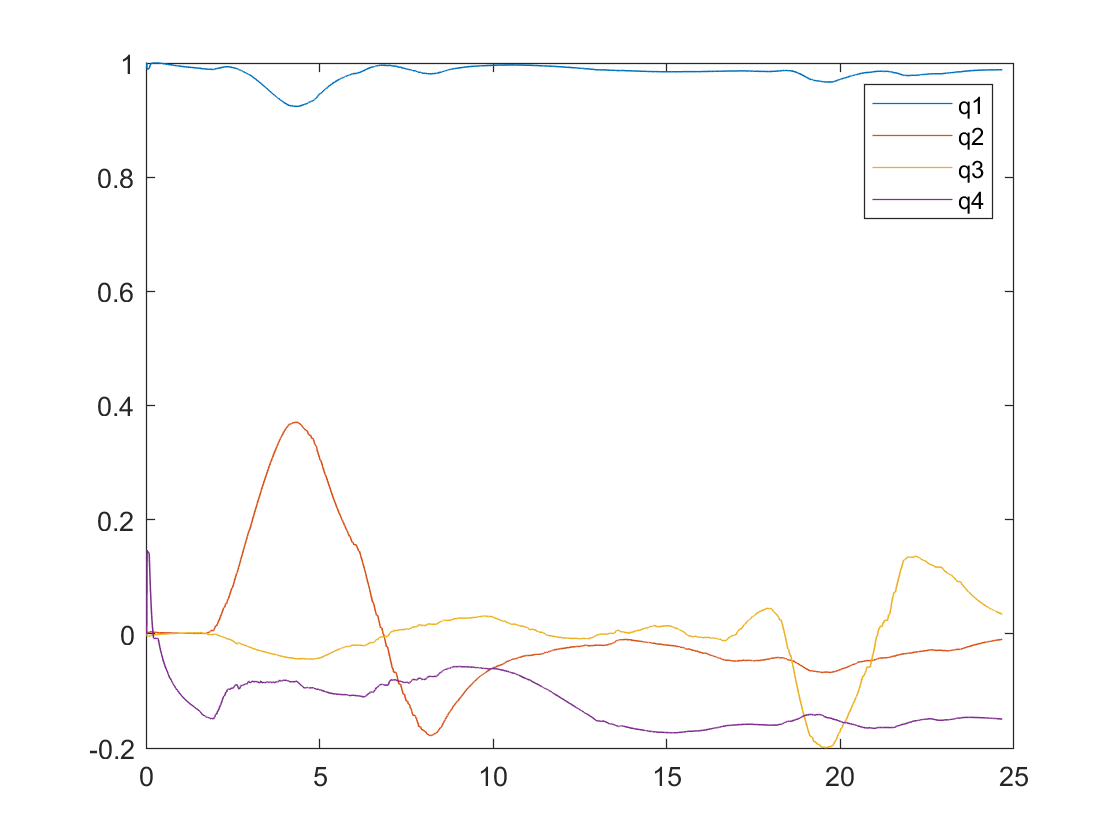

figure()
T_11 = xhat11.t(2:end);
plot(T_11, xhat11.x(1,:))
hold on
plot(T_11, xhat11.x(2,:))
plot(T_11, xhat11.x(3,:))
plot(T_11, xhat11.x(4,:))
hold off
legend('q1', 'q2', 'q3', 'q4')

% print('./Images/task11_mag_outlier_rej','-dpng')

## Converting to Euler angles

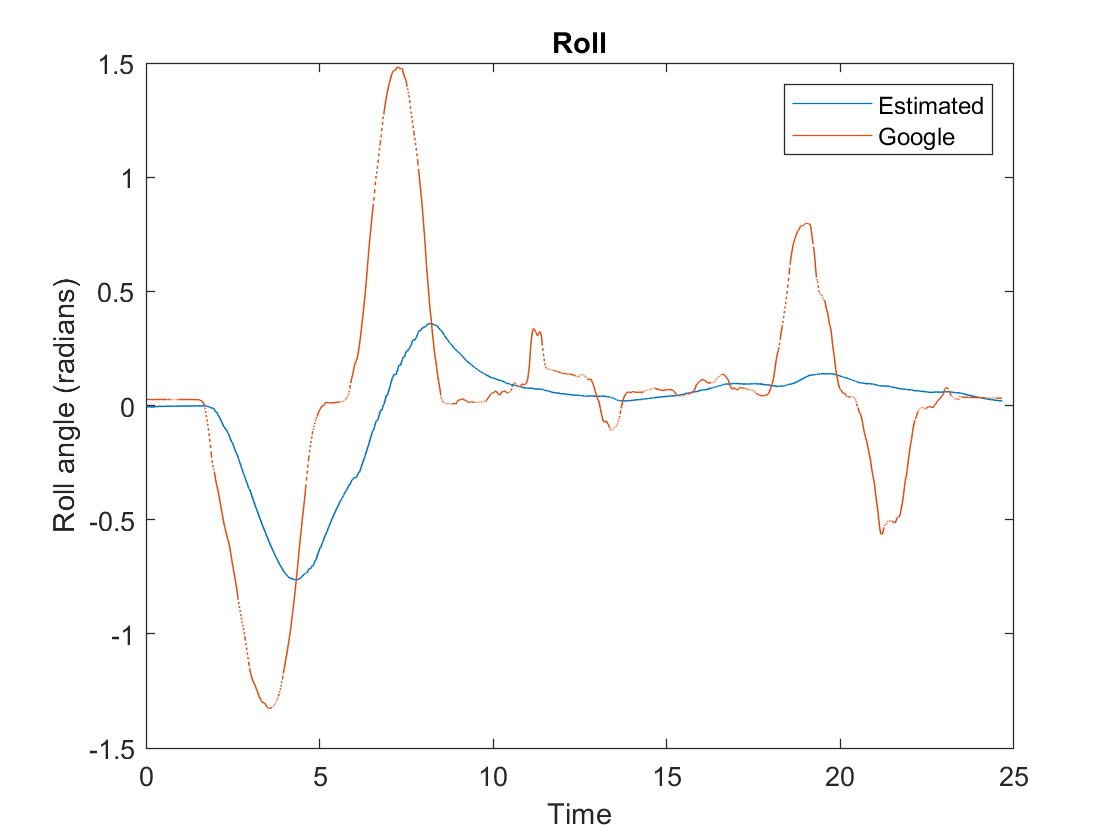

Estimated_euler = q2euler(xhat11.x);
Orientation_euler = q2euler(meas11.orient);

T12 = xhat11.t(2:end);
figure()
plot(T12, Estimated_euler(1,:))
hold on
plot(T12, Orientation_euler(1,:))
hold off
legend('Estimated', 'Google')
title('Roll')
xlabel('Time'), ylabel('Roll angle (radians)')
print('./Images/task12_acc_mag_roll','-dpng')

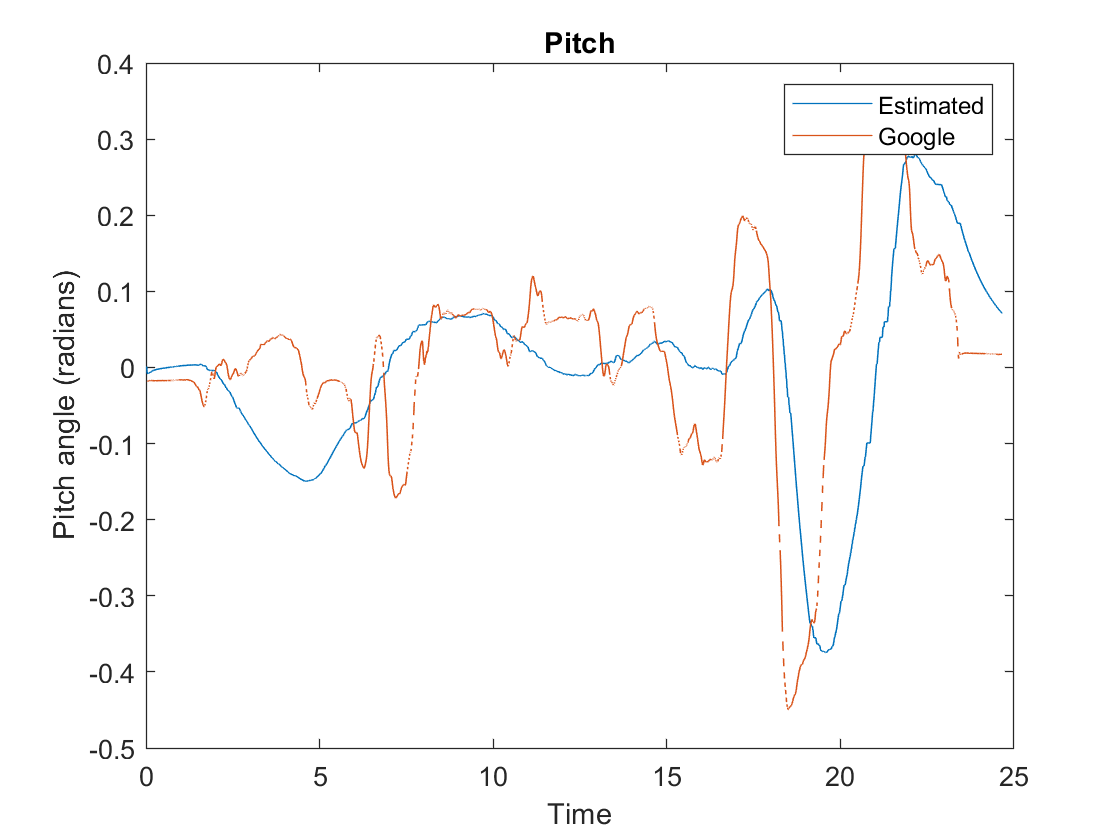


figure()
plot(T12, Estimated_euler(2,:))
hold on
plot(T12, Orientation_euler(2,:))
hold off
legend('Estimated', 'Google')
title('Pitch')
xlabel('Time'), ylabel('Pitch angle (radians)')
print('./Images/task12_acc_mag_pitch','-dpng')

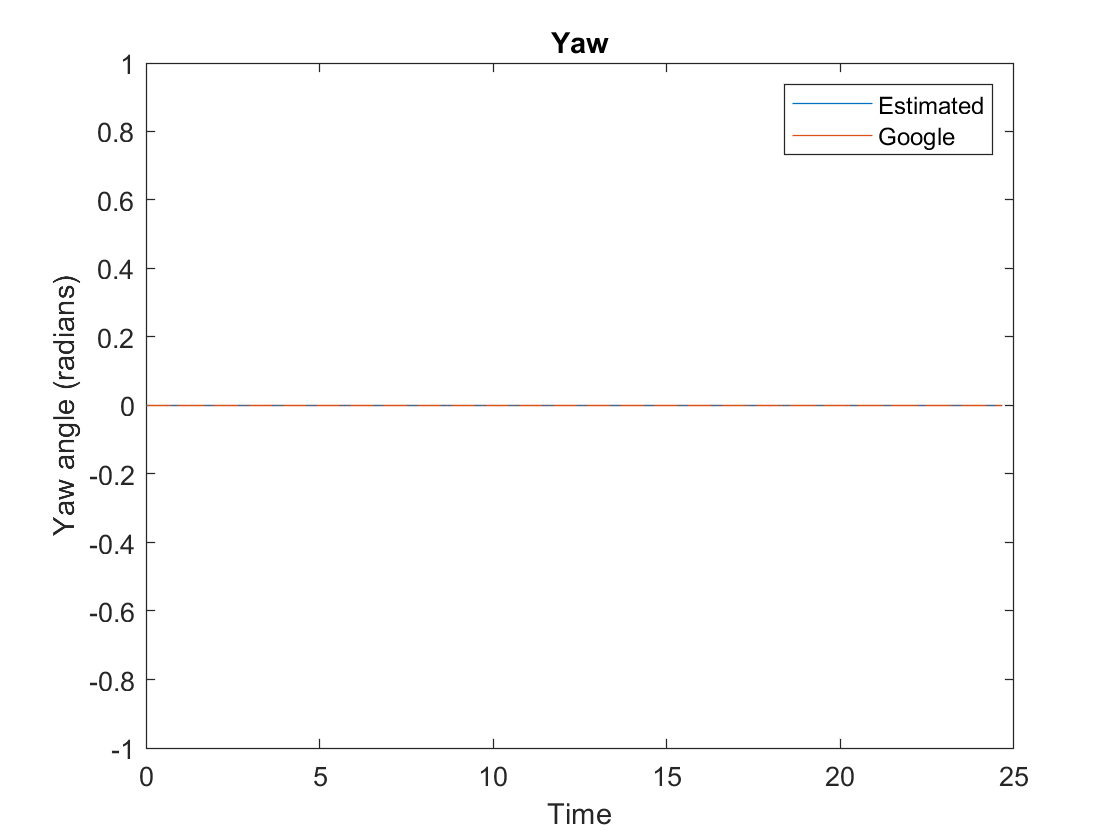


figure()
plot(T12, Estimated_euler(3,:))
hold on
plot(T12, Orientation_euler(3,:))
hold off
legend('Estimated', 'Google')
title('Yaw')
xlabel('Time'), ylabel('Yaw angle (radians)')
print('./Images/task12_acc_mag_yaw','-dpng')